# PGD CODE FOR 2D POISSON EQUATION

## Oriol CHANDRE VILA

## ISAE-SUPAERO, June 2018

Reproduction of the case presented in the book *The Proper Generalized Decomposition for Advanced Numerical Solution: A primer* of Chinesta, Keunings and Leygue.

clear all; close all; clc;
warning('off');

## Initializing the problem

Regarding the tolerances, two different values are defined in order to achieving faster results. This consideration does not effect the result of the problem. Also, the maximum number of enrichement steps it is defined at 4. 

% VARIABLES
global coords ndim dy dx nen TOL TOL_TILDE;
ndim = 2;
TOL = 1.0E-08; % Tolerance.
TOL_TILDE = 1.0E-05; % PGD enrichment tolerance.
num_max_iter = 4; % Max. # of functional pairs for the approximation.

For this approach, the domain of the problem is defined as $\Omega = \Omega_x \times \Omega_y = [0,2] \times [0,1]$. Finally, the number of elements in each direction of the mesh (*M*) is considered to be 101.

% GEOMETRY
X0 = 0; Xf = 2; Y0 = 0; Yf = 1; % The domain: [0,2]x[0,1]
nen = 101; % # elements for each direction
X = linspace(X0,Xf,nen); Y = linspace(Y0,Yf,nen);
coords = [X' Y'];
dx = coords(2,1) - coords(1,1);
dy = coords(2,2) - coords(1,2);

% ALLOCATION OF MATRICES AND VECTORS
F = zeros(numel(coords(:,1)),1); % Nodal values of spatial-X function F
G = zeros(numel(coords(:,2)),1); % Nodal values of spatial-Y function G
% These vectors are defined by: [#elem, #enrichment(n)]

In this problem, the source term is considered constant.

% SOURCE TERM IN SEPARATED FORM: f(x,y) = Fx(x)*Fy(y)
f = -1;
f_source(:,1) = f*ones(nen,1); % Fx(x)
f_source(:,2) = ones(nen,1); % Fy(y)

## The Offline Phase: The PGD Construction

The online phase of the PGD requires a robust offline computation. During this phase, the matrices *F(x) *and *G(y)* are computed and stored. The columns are the number of enrichment steps computed, while the rows are the number of elements.

And then, the PGD is constructed:

% SOLVING THE PROBLEM
[F,G] = PGD_Poisson_2D(num_max_iter);
fprintf(1,'PGD offline Process exited normally\n');

PGD offline Process exited normally


save('WorkSpacePGD_ParametricedPoisson.mat');

## Post-process

In this section, the different enrichment states of *F(x)* and *G(y)* are graphed. Also a surface plot of the complete solution.

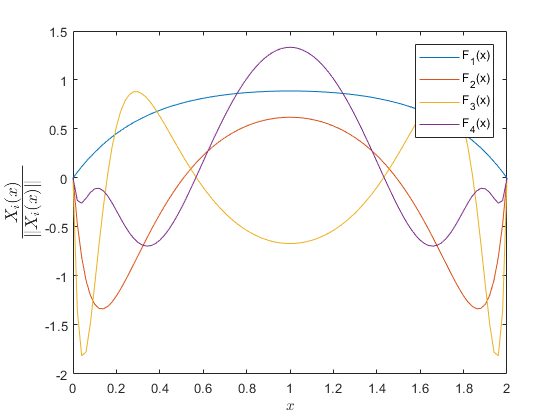

figInt = 0;
% NORMALIZATION OF THE COMPUTED FUNCTIONS
plotF = bsxfun(@rdivide,F,sqrt(trapz(coords(:,1),F.^2)));
plotG = bsxfun(@rdivide,G,sqrt(trapz(coords(:,2),G.^2)));

% F-i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(coords(:,1),plotF);
legend(handles,cellfun(@(in) ['F_' num2str(in) '(x)'],...
    num2cell(1:num_max_iter),'uniformoutput',false));
xlabel('$x$','interpreter','latex');
ylabel('$\frac{X_i(x)}{\|X_i(x)\| \,\,\, \,\,}$','interpreter','latex',...
    'fontsize',18);

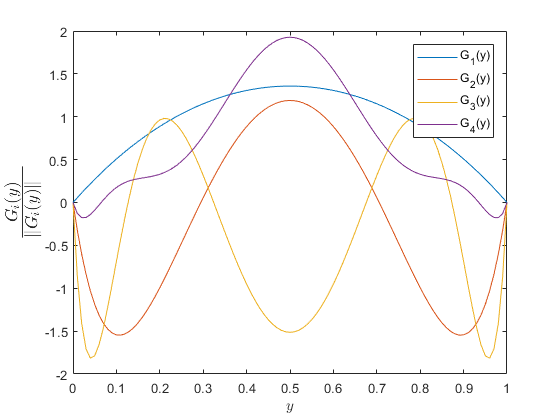


% G-i PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
handles = plot(coords(:,2),plotG);
legend(handles,cellfun(@(in) ['G_' num2str(in) '(y)'],...
    num2cell(1:num_max_iter),'uniformoutput',false));
xlabel('$y$','interpreter','latex');
ylabel('$\frac{G_i(y)}{\|G_i(y)\| \,\,\, \,\,}$','interpreter','latex',...
    'fontsize',18);

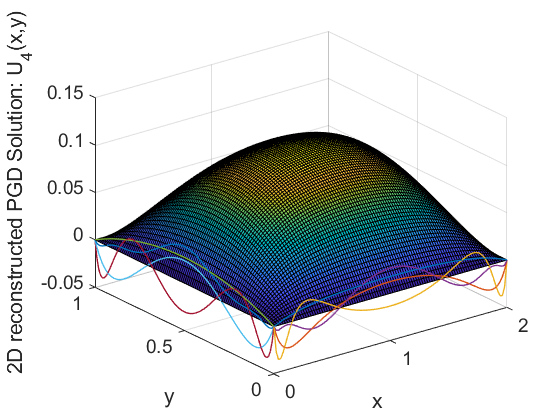


% SURFACE PLOT
figInt = figInt + 1;
figure(figInt);
set(gca,'fontsize',14);
grid on
hold on
plot3(coords(:,1),zeros(size(coords(:,1))),plotF/50,'linewidth',1);
plot3(zeros(size(coords(:,2))),coords(:,2),plotG/50,'linewidth',1);
surf(coords(:,1),coords(:,2),G*F');
colormap('default');
xlabel('x'); ylabel('y');
zlabel('2D reconstructed PGD Solution: U_4(x,y)','fontsize',10);
view(3);

For future works, it is basic to work with the approach parametric of the PGD in order to fasterly modify some parameters of the problem.

## *Appendix: function *PGD_Poisson_2D

function [F,G] = PGD_Poisson_2D(Max_terms)
% PGD solution for homogeneous Dirichlet boundary conditions of the 2D
% Poisson equation.
% For this example, we use simple second order FD with trapezoidal
% integration rule along each dimension.
%
% Outputs:
%       F,G :  computed PGD solution. F(x) and G(y).
%
% Inputs:
%       Max_terms: Desired maximum number of steps for the enrichment
%       process.
%
% The code is presented in the book: "The Proper Generalizeed Decomposition
% for Advanced Numerical Solutions, a primer"
% (Authors: Chinesta, Keunings and Leygue).

global coords dy dx nen TOL TOL_TILDE;

% ALLOCATION OF MATRICES AND VECTORS
F = zeros(nen,0); % Nodal values of spatial-X function F
G = zeros(nen,0); % Nodal values of spatial-Y function G

% DISCRETE OPERATORS ALONG EACH DIMENSION
% Identity matrix long each dimension
Ix = speye(nen);
Iy = speye(nen);
% 2nd-order Finite Differences differentiation matrices
D2x = spdiags([ones(nen,1)  -2*ones(nen,1)  ones(nen,1)],...
    [-1 0 1],nen,nen)/dx^2;
D2y = spdiags([ones(nen,1)  -2*ones(nen,1)  ones(nen,1)],...
    [-1 0 1],nen,nen)/dy^2;

% SOURCE TERM IN A SEPARATED FORM: f(x,y) = fx(x)*fy(y)
f = -1;
fx = f*ones(nen,1);
fy = ones(nen,1);

% Number of a priori known terms
N0 = size(F,2);

% FIXED POINT ALGORITHM (main enrichement loop)
for term = (N0+1):(Max_terms+N0)
    % Initialization
    R = randn(nen,1);
    S = randn(nen,1);
    
    % Homogeneous Dirichlet boundary conditions
    R(1) = 0; R(end) = 0;
    S(1) = 0; S(end) = 0;
    
    imax = 150; % # iterations of fixed point iterations
    for iter = 1:imax
        R_old = R; S_old = S;
        % LOOKING FOR R, KNOWNING S
        % Construction of the 1D Problem
        alpha_x = trapz(coords(:,2),S.^2);
        beta_x  = trapz(coords(:,2),S.*(D2y*S));
        ksi_x = trapz(coords(:,2),S.*fy);
        RHS = ksi_x*fx;
        % In case this is not the first enrichment:
        if (term > 1)
            gamma_x_i = trapz(coords(:,2),bsxfun(@times,S,G));
            delta_x_i = trapz(coords(:,2),bsxfun(@times,S,D2y*G));
            RHS = RHS -(D2x*F)*gamma_x_i' - F*delta_x_i';
        end
        % Solving the 1D Problem
        A = alpha_x*D2x + beta_x*Ix;
        R(2:end-1) = A(2:end-1,2:end-1)\RHS(2:end-1);
        
        % LOOKING FOR R, KNOWNING S
        % Construction of the 1D Problem
        alpha_y = trapz(coords(:,1),R.^2);
        beta_y  = trapz(coords(:,1),R.*(D2x*R));
        ksi_y = trapz(coords(:,1),R.*fx);
        RHS = ksi_y*fy;
        % In case this is not the first enrichment:
        if (term > 1)
            gamma_y_i = trapz(coords(:,1),bsxfun(@times,R,F));
            delta_y_i = trapz(coords(:,1),bsxfun(@times,R,D2x*F));
            RHS = RHS -(D2y*G)*gamma_y_i' - G*delta_y_i';
        end
        % Solving the 1D Problem
        A = alpha_y*D2y + beta_y*Iy;
        S(2:end-1) = A(2:end-1,2:end-1)\RHS(2:end-1);
        
        % STOPPING CRITERION FOR FIXED POINT ITERATIONS
        % Norm of the difference between the 2 fixed point iterations
        S_diff = sqrt(trapz(coords(:,1),R.^2)*trapz(coords(:,2),S.^2)...
            + trapz(coords(:,1),R_old.^2)*trapz(coords(:,2),S_old.^2)...
            - 2*trapz(coords(:,1),R.*R_old)*trapz(coords(:,2),S.*S_old));
        if(S_diff < TOL)
            break;
        end
    end
    
    % NORMALIZING THE NEW ENRICHMENT STEP AND ADDING TO THE EXISTING ONES:
    fact_x = sqrt(trapz(coords(:,1),R.^2)/(coords(end,1)-coords(1,1))^2);
    fact_y = sqrt(trapz(coords(:,2),S.^2)/(coords(end,2)-coords(1,2))^2);
    fact_xy = sqrt(fact_x*fact_y);
    F = [F fact_xy*R/fact_x]; G = [G fact_xy*S/fact_y];
    
    % STOPPING CRITERION FOR ENRICHMENT PROCESS
    Error_iter = sqrt(trapz(coords(:,1),R.^2)*trapz(coords(:,2),S.^2))...
        / sqrt(trapz(coords(:,1),F(:,N0+1).^2)*trapz(coords(:,1),...
        G(:,N0+1).^2));
    if(Error_iter < TOL_TILDE)
        break;
    end
end
end